# Plot Electricity Trend

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

resElectricity = readtable("../data/electricity.csv")

resElectricity = 315×5 table
       Date       Residential    Commercial    Industrial      Total   
    __________    ___________    __________    __________    __________

    01/01/1990     9.542e+07     6.2499e+07    7.5188e+07    2.4087e+08
    02/01/1990    7.4498e+07     5.6912e+07    7.4607e+07    2.1336e+08
    03/01/1990    7.1902e+07      5.798e+07    7.6842e+07    2.1407e+08
    04/01/1990    6.5191e+07     5.6481e+07    7.6238e+07    2.0507e+08
    05/01/1990    6.2881e+07     5.8941e+07    7.8759e+07    2.0815e+08
    06/01/1990      7.39e+07     6.4609e+07    8.0676e+07    2.2704e+08
    07/01/1990    9.0935e+07     7.0948e+07    8.1116e+07    2.5159e+08
    08/01/1990    8.8564e+07     7.1119e+07    8.4045e+07    2.5211e+08
    09/01/1990     8.624e+07     6.9296e+07    8.1611e+07    2.4518e+08
    10/0

residential = resElectricity.Residential;
residential(isnan(residential)) = 1e8;
yr = resElectricity.Date;
p = polyfit(1:length(yr), residential, 3);
resFitted = polyval(p, 1:length(yr));

## Task 1

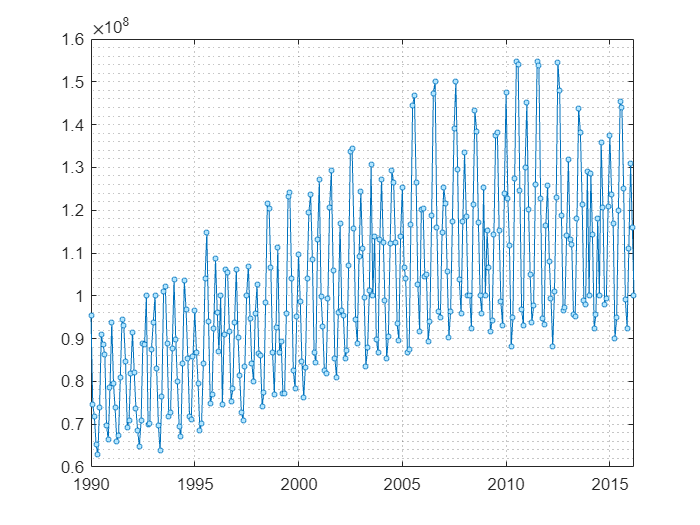

plot(yr, residential, "o-", "MarkerSize", 3, "MarkerFaceColor", [0.7 0.9 1])
grid minor

## Task 2

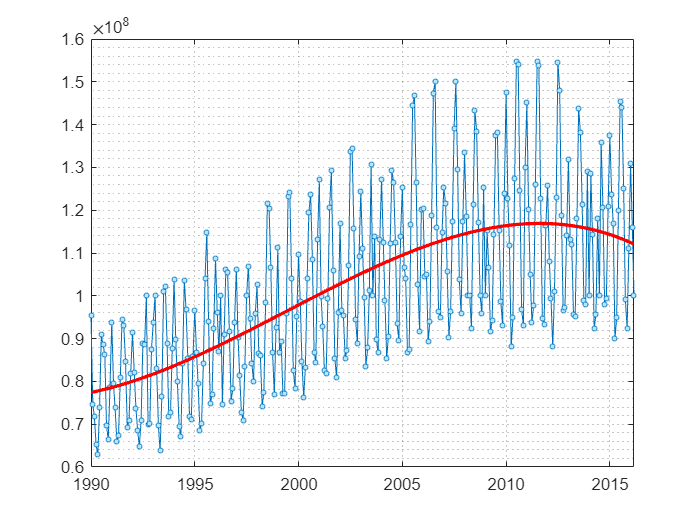

hold on
plot(yr, resFitted, "r", "LineWidth", 2)
hold off